# Neural-Network 2

Created time : 2024/5/17 09:20

學號 : 109321019    姓名 : 涂价弘

clear
clc

## 步驟1：加載圖像樣本數據，並顯示其中的部分圖像

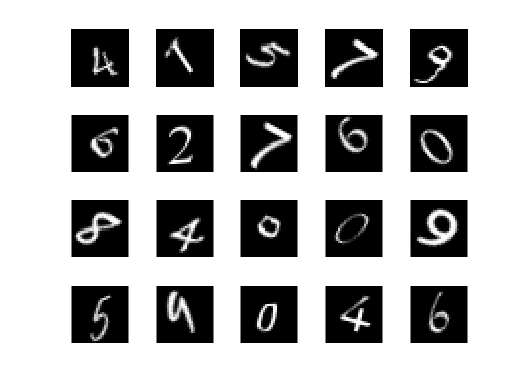

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

## 步驟2：將加載的圖像樣本分為訓練集和測試集（註：在本例中，訓練集的數量為750幅，剩餘的為測試集）

numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## 步驟3：構建卷積網絡（註：可以在該部分進行相關參數的設置改進）

layers = [
    imageInputLayer([28 28 1])                    % 输入层，1个通道，像素为28×28

    convolution2dLayer([3 3],8,'Padding','same')  % 卷积层1：卷积核大小为3×3，卷积核的个数为8（每个卷积核的通道数与输入图像的通道数相等，本层中每个卷积核1个通道）卷积的方式采用零填充方式（即设定为same方式）
    batchNormalizationLayer                       % 批量归一化层1
    reluLayer                                     % ReLu非线性激活函数1
    maxPooling2dLayer(2,'Stride',2)               % 池化层1：池化方式：最大池化；池化区域为2×2，步长为2

    convolution2dLayer([3 3],16,'Padding','same') % 卷积层2：卷积核大小为3×3，卷积核的个数为16（每个卷积核的通道数与输入特征图的通道数相等，本层中每个卷积核8个通道）卷积的方式采用零填充方式（即设定为same方式）
    batchNormalizationLayer                       % 批量归一化层2
    reluLayer                                     % ReLu非线性激活函数2
    maxPooling2dLayer(2,'Stride',2)               % 池化层2：池化方式：最大池化；池化区域为2×2，步长为2

    fullyConnectedLayer(10)                       % 全连接层：将全连接层输出的个数设置为10个
    softmaxLayer                                  % softmaxLayer层：输出每个输出的概率
    classificationLayer ];                        % 分类层：根据上一层的输入的概率，进行分类并输出


analyzeNetwork(layers)

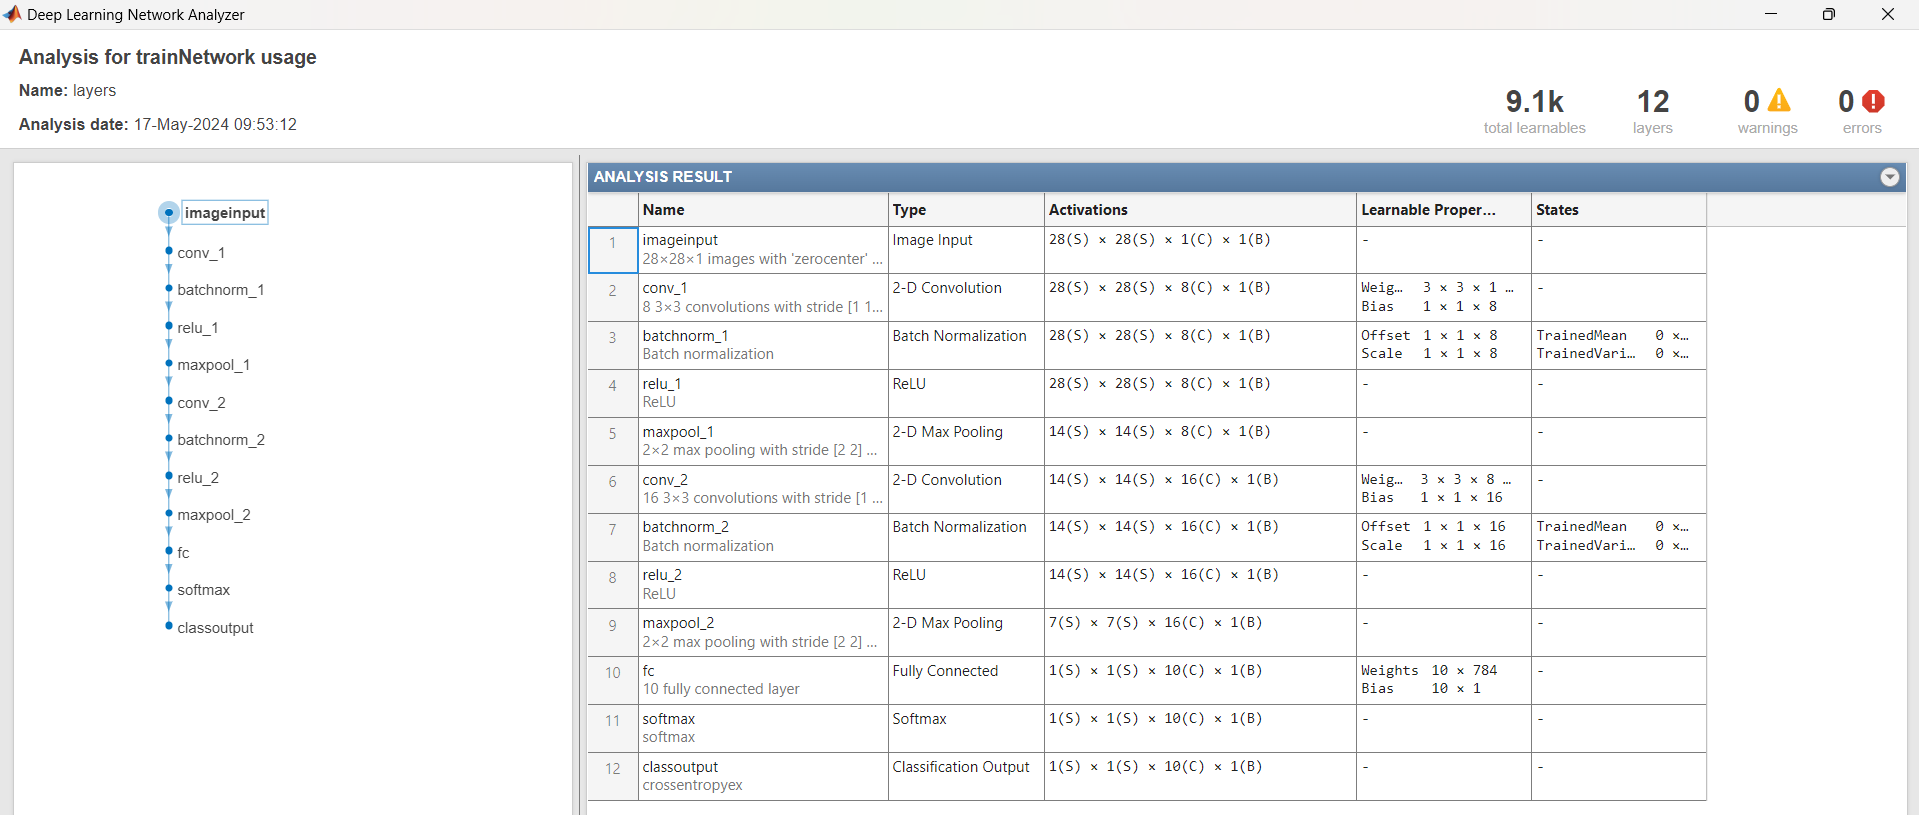

## 步驟4：配置訓練選項並開始訓練

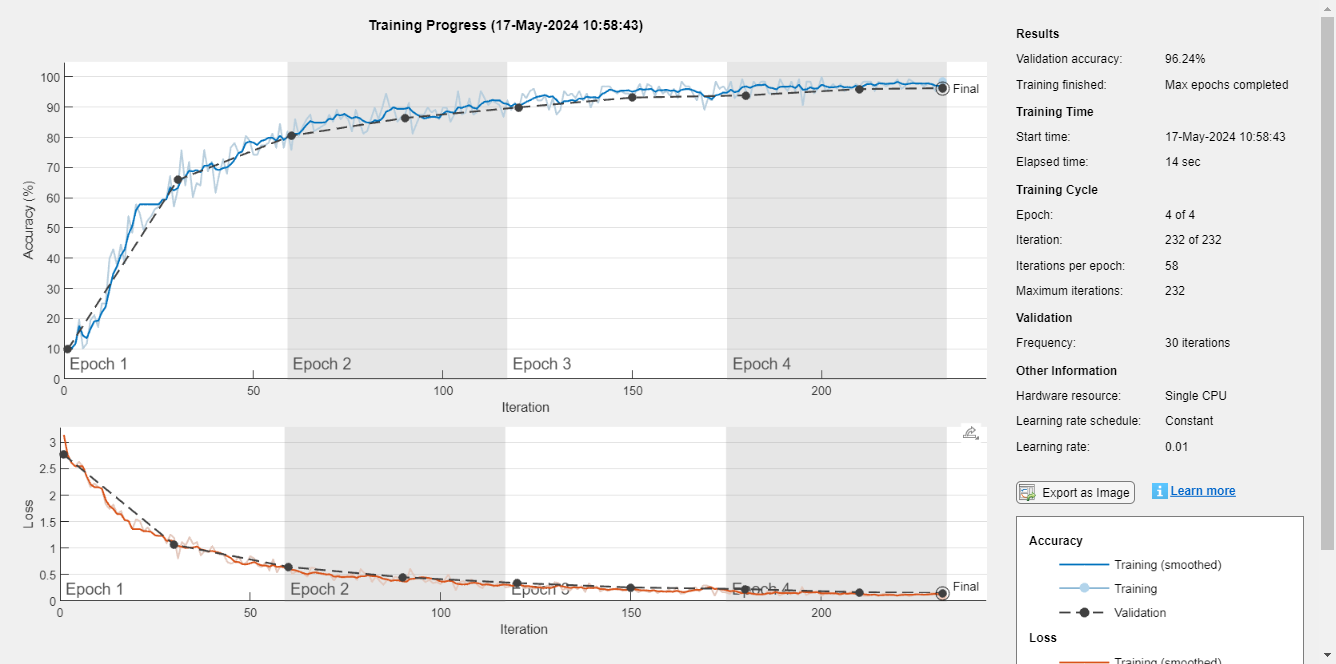

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

% 配置训练选项
%'sgdm'表示使用具有动量的随机梯度下降方法来训练网络；'InitialLearnRate'设置初始学习率为0.01；'MaxEpochs'将最大训练轮数设置为4；'Shuffle'表示打乱数据，'every-epoch'则代表每一轮训练都打乱一次数据；'ValidationData'用于设置验证数据集，'ValidationFrequency'设置验证频率为30；'Verbose'设置为false则不显示进度信息；'Plots'打开训练进度图。

net = trainNetwork(imdsTrain,layers,options); %对网络进行训练

## 步驟5：將訓練好的網絡用於對新的輸入圖像進行分類，並計算準確率

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9624

## Default layer

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer([3 3],16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

## Exercise-1-1

去掉第二層卷積層

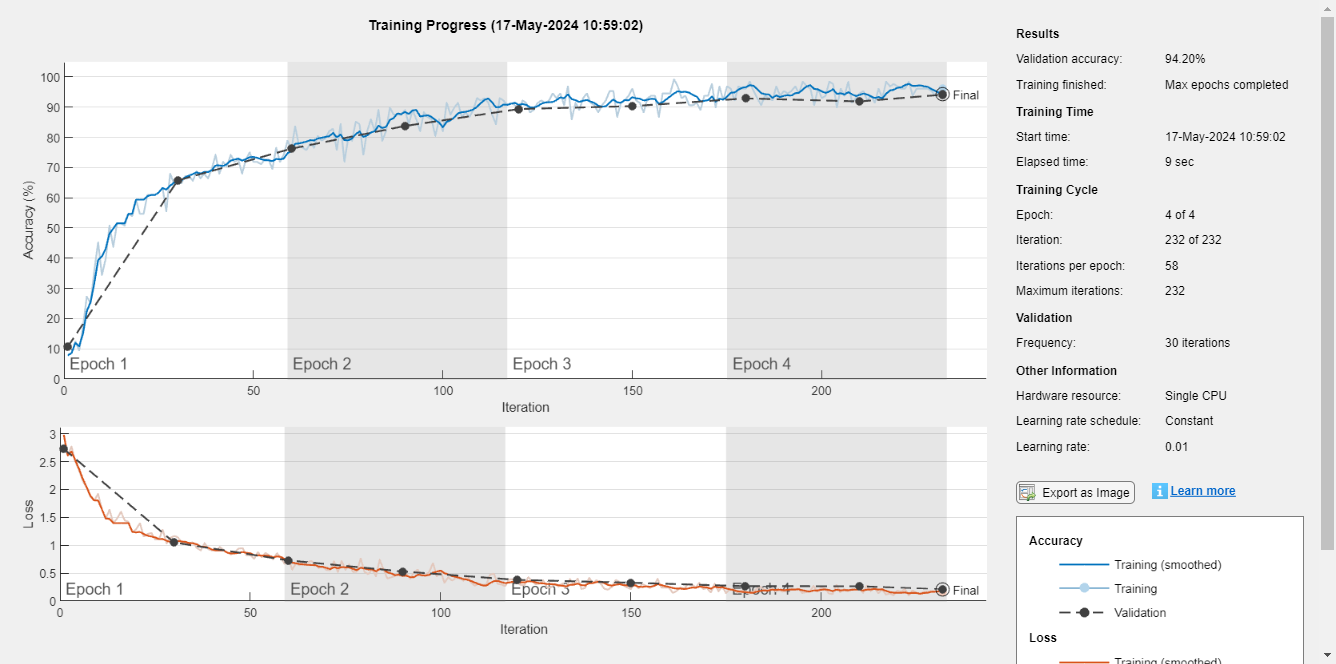

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9420

## Exercise-1-2

第一層卷積層 filter size = 4

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],4,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

net = trainNetwork(imdsTrain,layers,options);

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.8892

analyzeNetwork(layers)

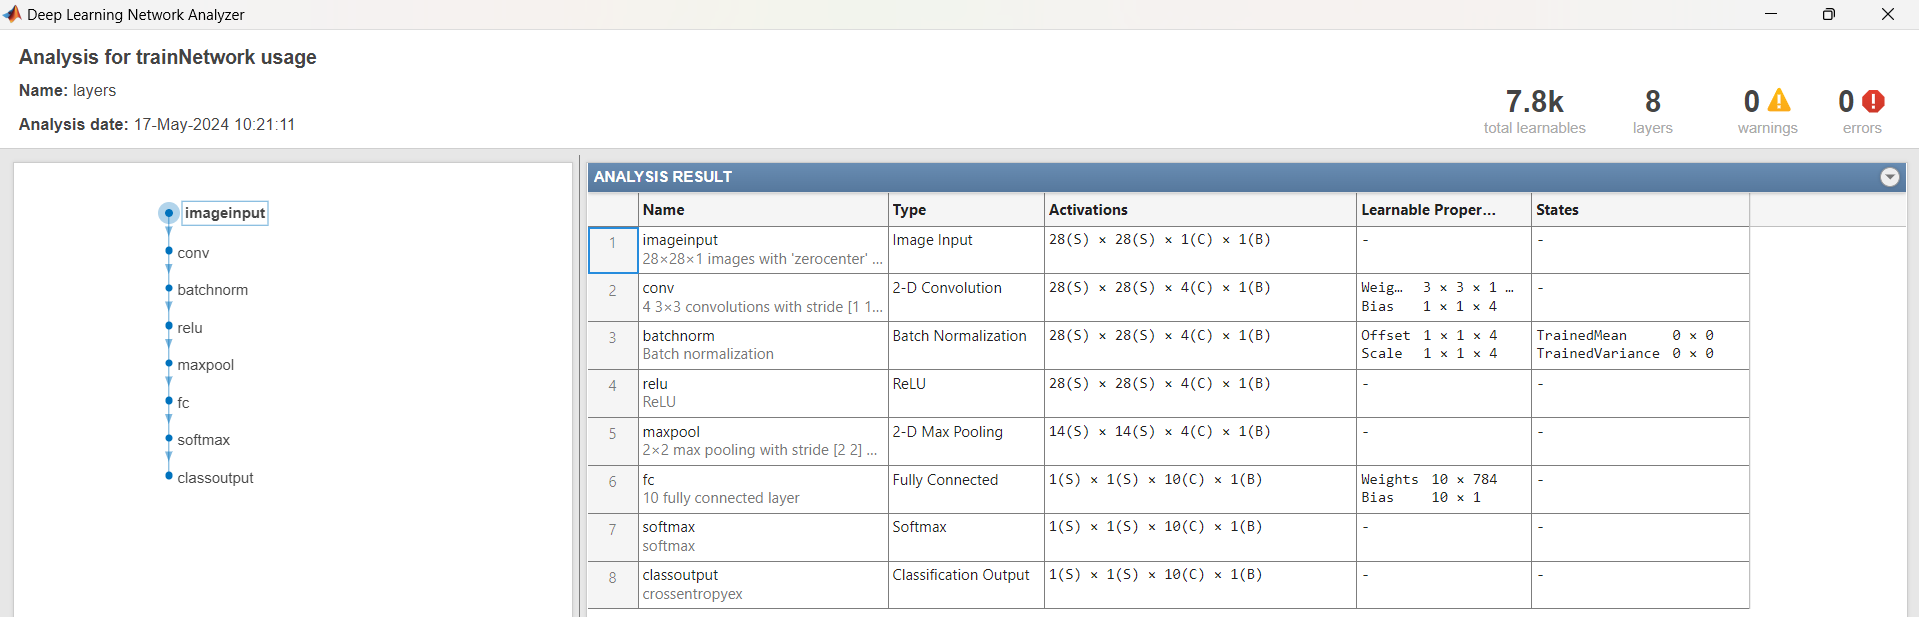

## Exercise-2-1

去掉所有 batch normalization

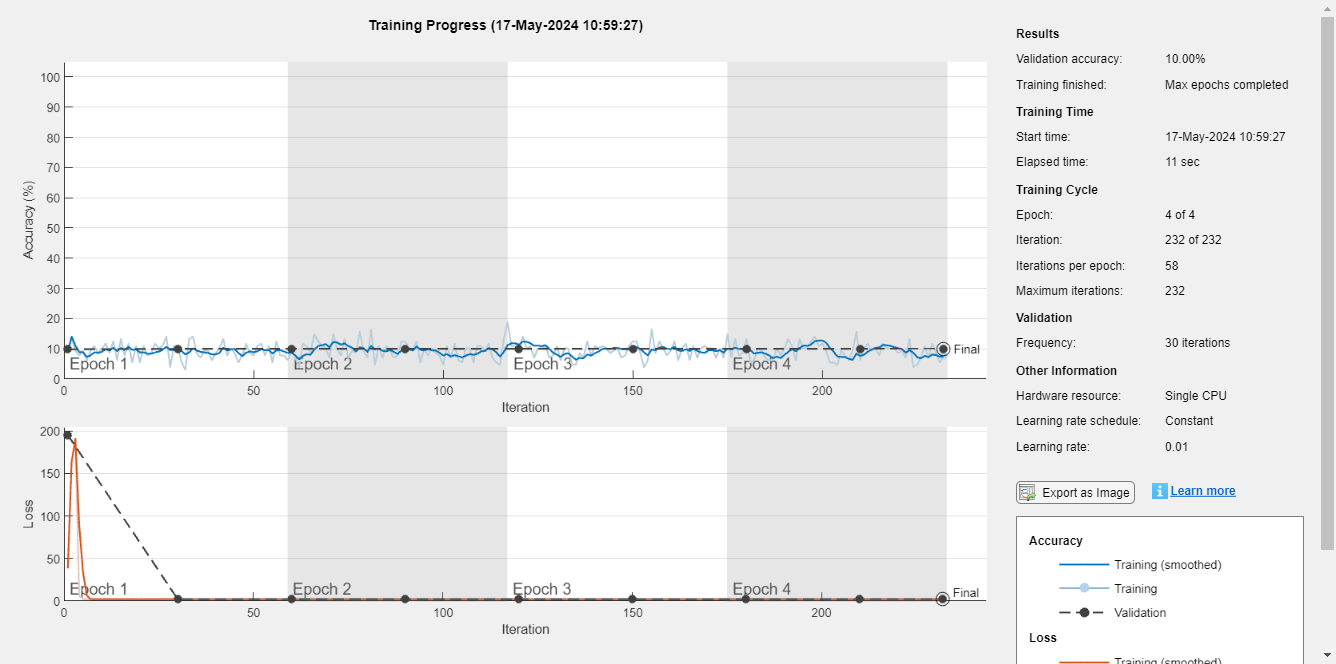

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],8,'Padding','same')
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer([3 3],16,'Padding','same')
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.1000

## Exercise-2-2

僅去掉第一個 batch normalization

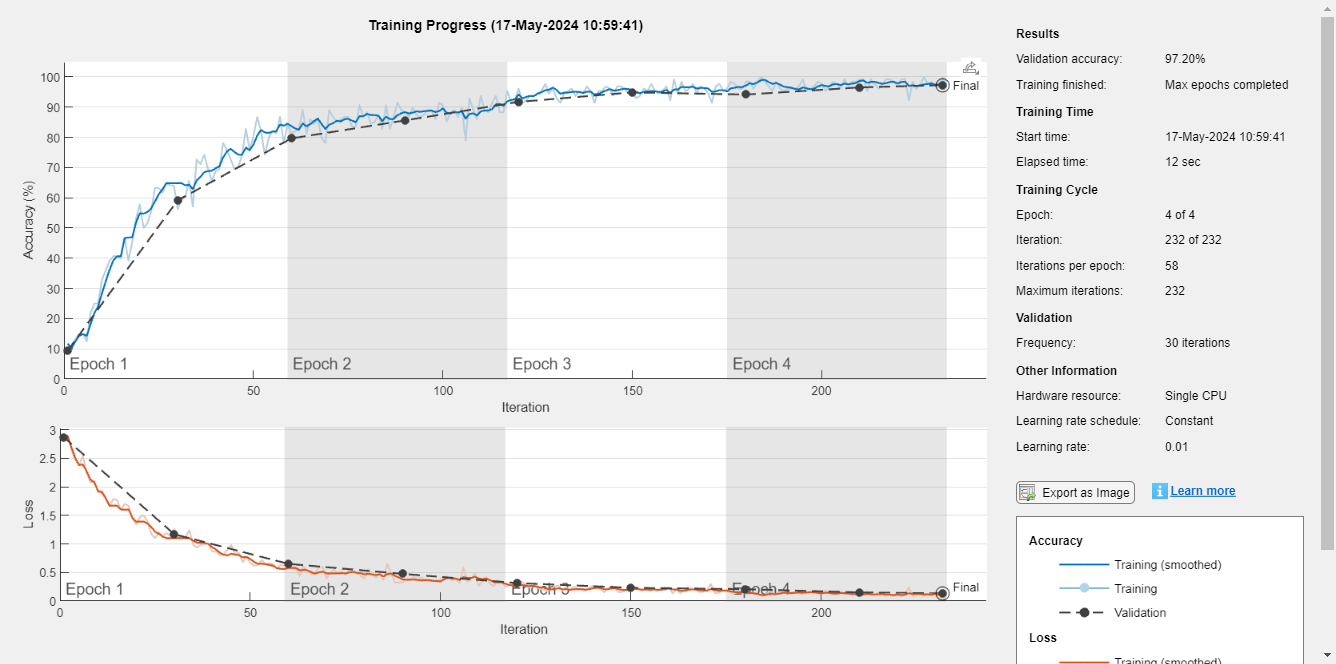

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],8,'Padding','same')
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer([3 3],16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9720

## Exercise-2-3

僅去掉第二個 batch normalization

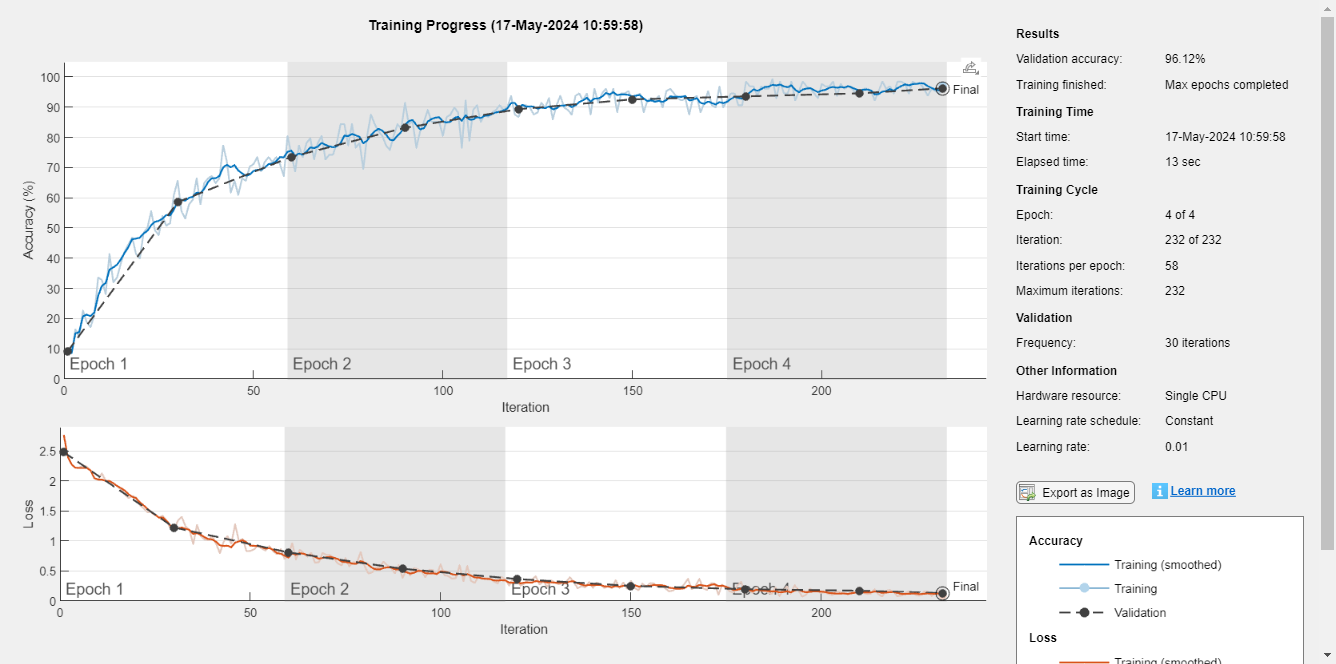

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer([3 3],16,'Padding','same')
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9612

## Exercise-3-1

去掉所有 relu activation

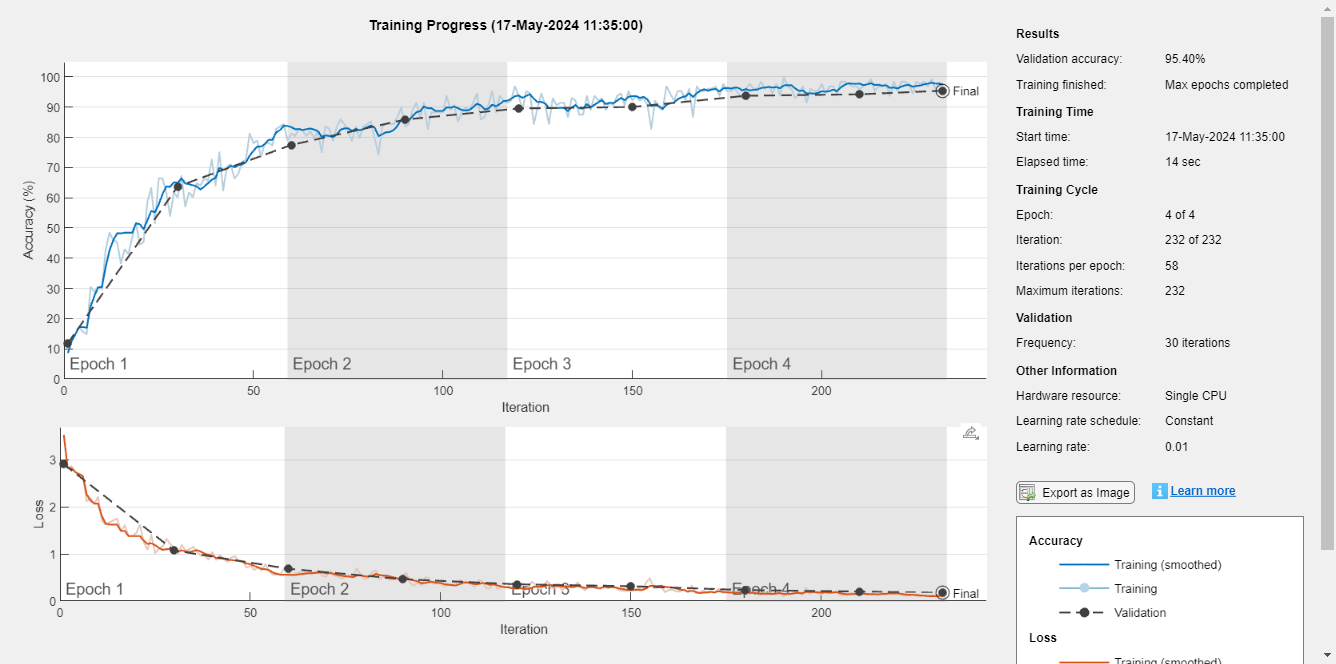

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],8,'Padding','same')
    batchNormalizationLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer([3 3],16,'Padding','same')
    batchNormalizationLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9540

## Exercise-3-2

activation function 改成 tanh

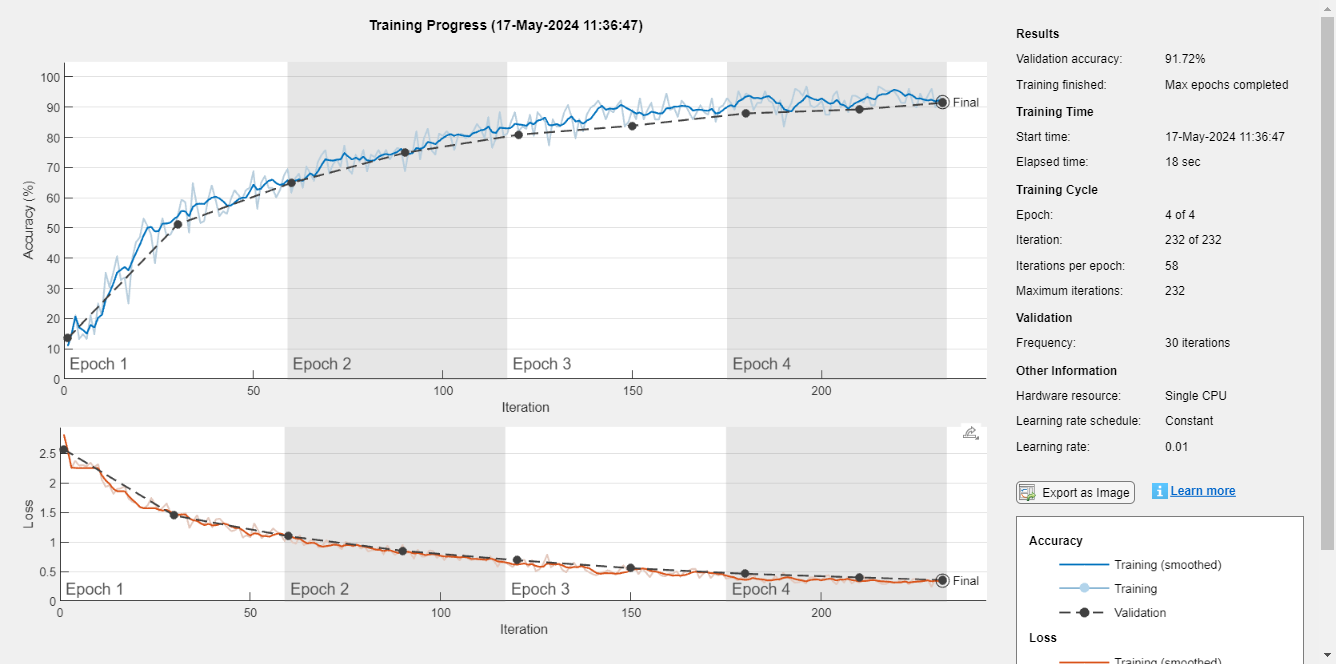

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],8,'Padding','same')
    batchNormalizationLayer
    tanhLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer([3 3],16,'Padding','same')
    batchNormalizationLayer
    tanhLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9172

## Exercise-4-1

去掉所有 pooling

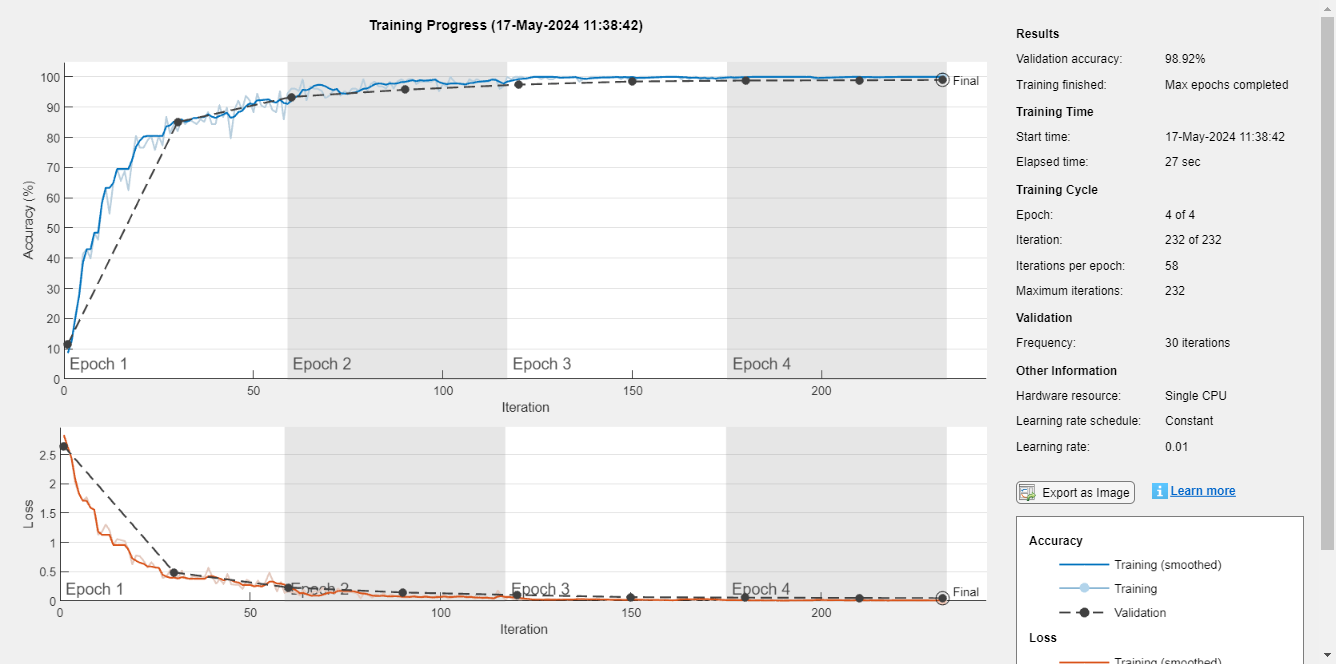

accuracy = 0.9892

## Exercise-4-2

去掉第一個 pooling

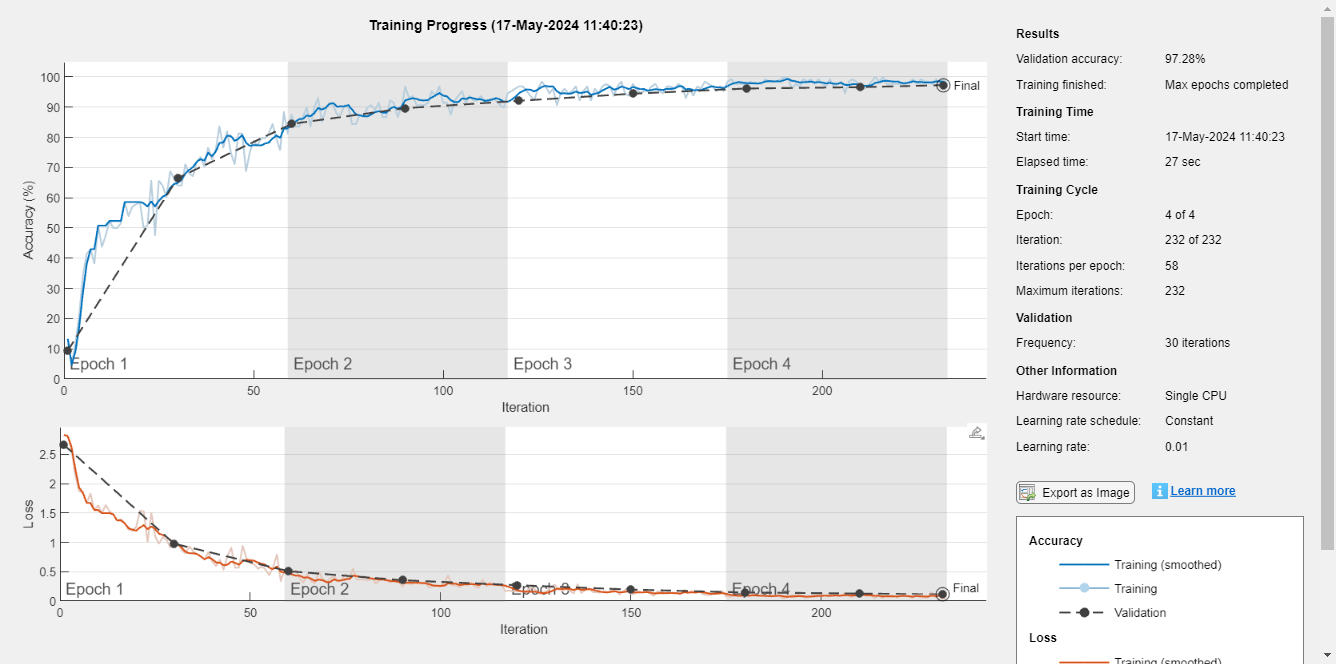

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    % maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer([3 3],16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9728

## Exercise-4-3

將所有 pooling 的 stride 改成 4

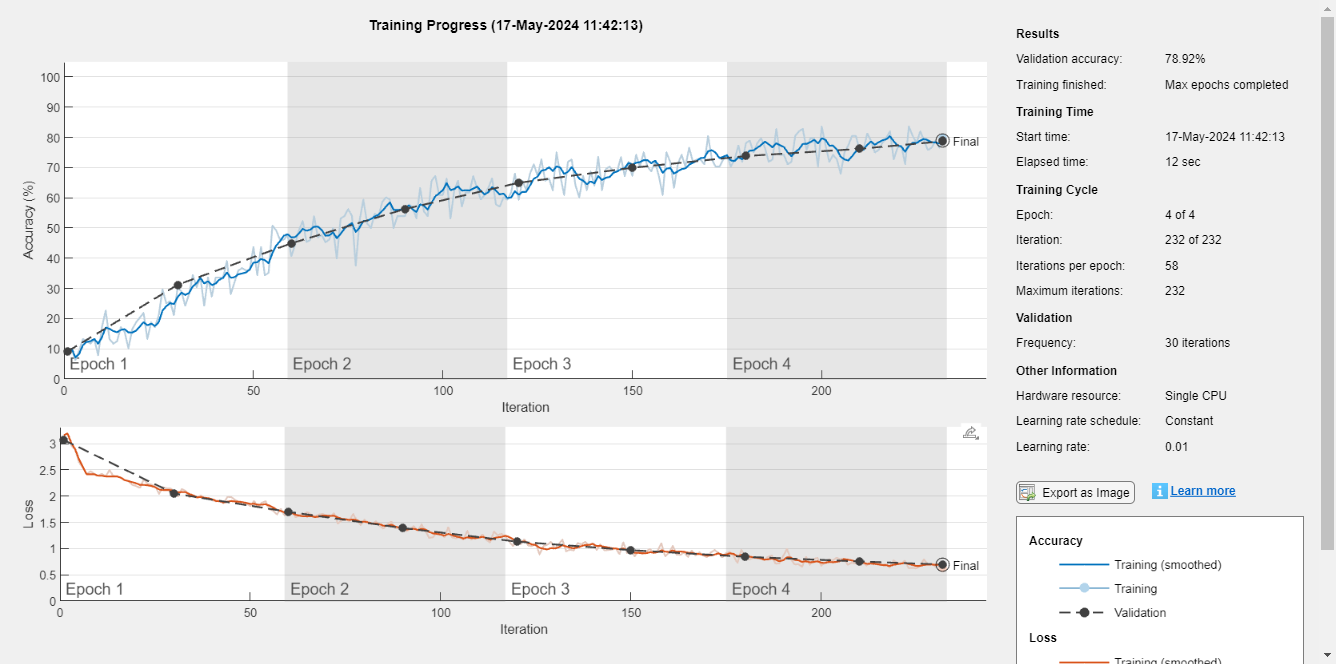

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',4)

    convolution2dLayer([3 3],16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',4)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.7892

## Exercise-5

辨識自己的手寫圖

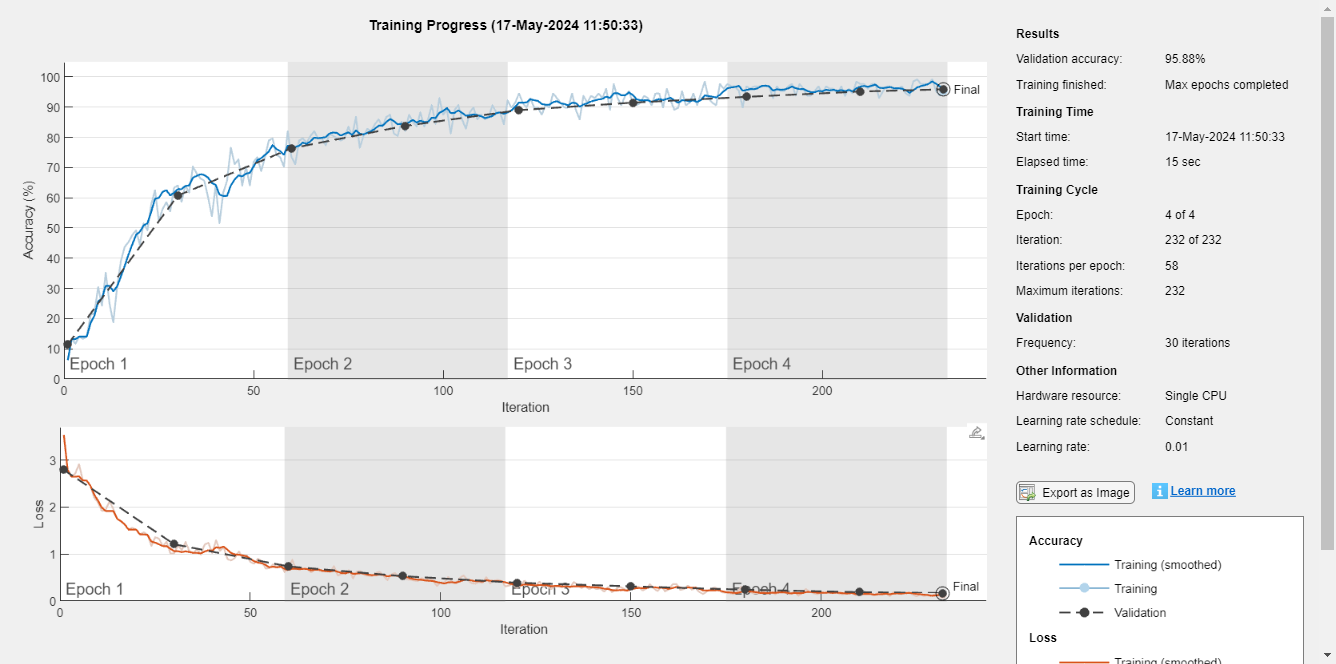

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer([3 3],8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer([3 3],16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer ];

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation) / numel(YValidation)

accuracy = 0.9588

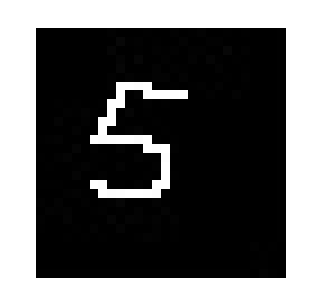

clf('reset')

I = imread('./images/hand_write_5.png');
Ig = reshape(rgb2gray(I), [28, 28, 1]);
imshow(Ig)
truesize([200 200])

classify(net, Ig)

ans = categorical
     5 
